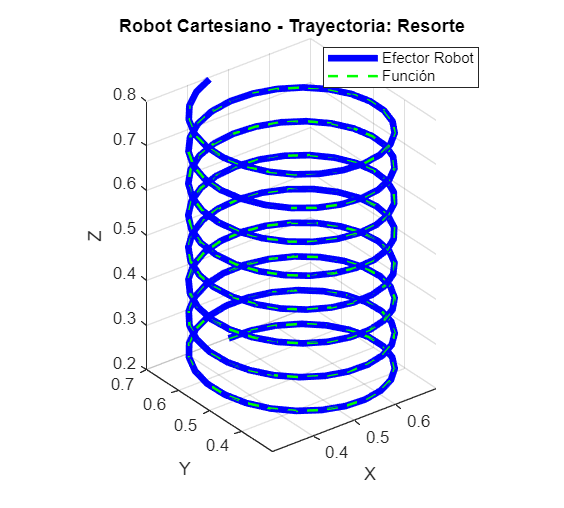

%% Seguimiento de Trayectorias 3D - Robot Cartesiano (PPP)
clc; clear; close all;

% Parámetro constante del Robot (Altura de la base)
l1 = 1.0; 

%% ==========================================================
%  TRAYECTORIA 1: RESORTE
%  ==========================================================
t_res = 0:0.05:10;
xc = 0.5; yc = 0.5; 
r_res = 0.2; 

x_res = xc + (r_res .* sin(t_res * 5));
y_res = yc + (r_res .* cos(t_res * 5));
z_res = 0.2 + (t_res * 0.06); % Z subiendo progresivamente

N_res = length(t_res);
x0_res = zeros(1, N_res); y0_res = zeros(1, N_res); z0_res = zeros(1, N_res);
d1_res = zeros(1, N_res); d2_res = zeros(1, N_res); d3_res = zeros(1, N_res);

for i = 1:N_res
    [d1_res(i), d2_res(i), d3_res(i)] = cinv_Cartesiano(l1, x_res(i), y_res(i), z_res(i));
    [x0_res(i), y0_res(i), z0_res(i)] = cdir_Cartesiano(d1_res(i), d2_res(i), d3_res(i), l1);
end

% Gráfica 3D
figure('Name', 'Trayectoria 1: Resorte (3D)', 'Position', [50, 500, 500, 450]);
plot3(x0_res, y0_res, z0_res, 'b', 'LineWidth', 4); hold on;
plot3(x_res, y_res, z_res, '--g', 'LineWidth', 1.5);
axis equal; grid on; title('Robot Cartesiano - Trayectoria: Resorte');
legend("Efector Robot", "Función", 'Location', 'best'); xlabel('X'); ylabel('Y'); zlabel('Z'); view(3);

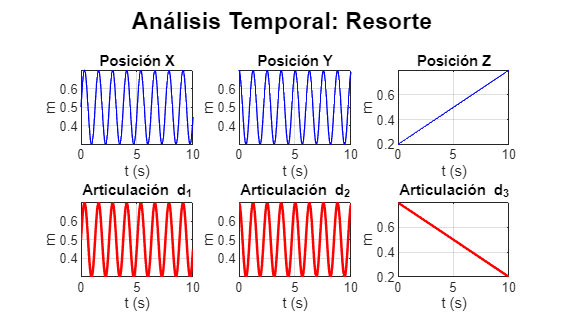


% Análisis Temporal
plotAnalisisTemporal(t_res, x_res, y_res, z_res, x0_res, y0_res, z0_res, d1_res, d2_res, d3_res, 'Resorte');

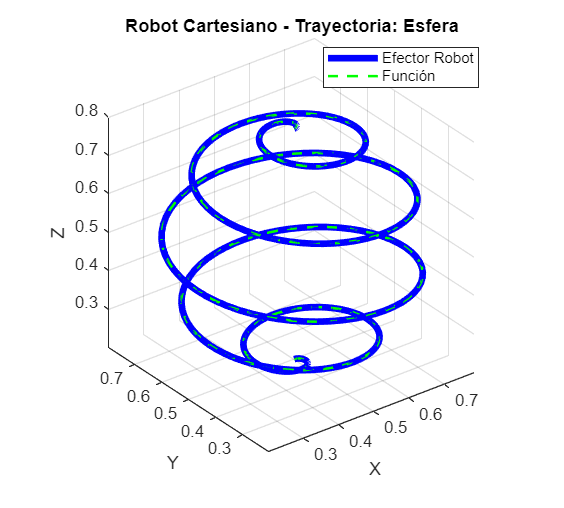


%% ==========================================================
%  TRAYECTORIA 2: ESFERA
%  ==========================================================
t_esf = 0:0.01:pi;
x_esf = 0.3 .* sin(t_esf) .* cos(10 * t_esf) + 0.5;
y_esf = 0.3 .* sin(t_esf) .* sin(10 * t_esf) + 0.5;
z_esf = 0.3 .* cos(t_esf) + 0.5;

N_esf = length(t_esf);
x0_esf = zeros(1, N_esf); y0_esf = zeros(1, N_esf); z0_esf = zeros(1, N_esf);
d1_esf = zeros(1, N_esf); d2_esf = zeros(1, N_esf); d3_esf = zeros(1, N_esf);

for i = 1:N_esf
    [d1_esf(i), d2_esf(i), d3_esf(i)] = cinv_Cartesiano(l1, x_esf(i), y_esf(i), z_esf(i));
    [x0_esf(i), y0_esf(i), z0_esf(i)] = cdir_Cartesiano(d1_esf(i), d2_esf(i), d3_esf(i), l1);
end

% Gráfica 3D
figure('Name', 'Trayectoria 2: Esfera (3D)', 'Position', [50, 50, 500, 450]);
plot3(x0_esf, y0_esf, z0_esf, 'b', 'LineWidth', 4); hold on;
plot3(x_esf, y_esf, z_esf, '--g', 'LineWidth', 1.5);
axis equal; grid on; title('Robot Cartesiano - Trayectoria: Esfera');
legend("Efector Robot", "Función", 'Location', 'best'); xlabel('X'); ylabel('Y'); zlabel('Z'); view(3);

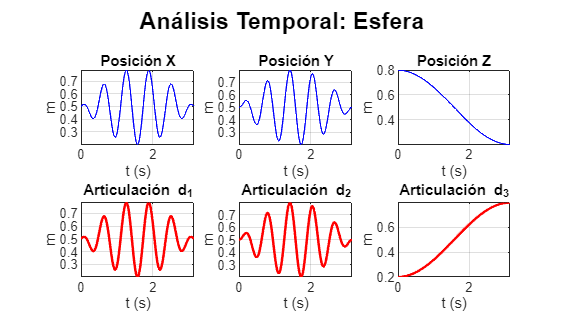


% Análisis Temporal
plotAnalisisTemporal(t_esf, x_esf, y_esf, z_esf, x0_esf, y0_esf, z0_esf, d1_esf, d2_esf, d3_esf, 'Esfera');

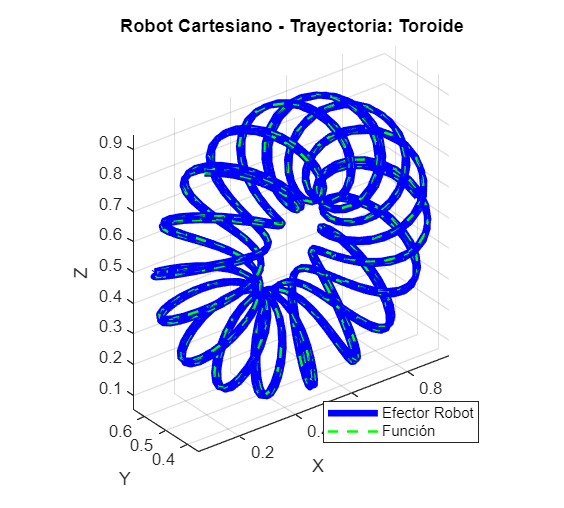


%% ==========================================================
%  TRAYECTORIA 3: TOROIDE
%  ==========================================================
t_tor = 0:0.05:40;
x_tor = (0.3 + 0.15 .* cos(sqrt(32) .* t_tor)) .* cos(t_tor) + 0.5;
y_tor = 0.15 .* sin(sqrt(32) .* t_tor) + 0.5;
z_tor = (0.3 + 0.15 .* cos(sqrt(32) .* t_tor)) .* sin(t_tor) + 0.5;

N_tor = length(t_tor);
x0_tor = zeros(1, N_tor); y0_tor = zeros(1, N_tor); z0_tor = zeros(1, N_tor);
d1_tor = zeros(1, N_tor); d2_tor = zeros(1, N_tor); d3_tor = zeros(1, N_tor);

for i = 1:N_tor
    [d1_tor(i), d2_tor(i), d3_tor(i)] = cinv_Cartesiano(l1, x_tor(i), y_tor(i), z_tor(i));
    [x0_tor(i), y0_tor(i), z0_tor(i)] = cdir_Cartesiano(d1_tor(i), d2_tor(i), d3_tor(i), l1);
end

% Gráfica 3D
figure('Name', 'Trayectoria 3: Toroide (3D)', 'Position', [50, 500, 500, 450]);
plot3(x0_tor, y0_tor, z0_tor, 'b', 'LineWidth', 4); hold on;
plot3(x_tor, y_tor, z_tor, '--g', 'LineWidth', 1.5);
axis equal; grid on; title('Robot Cartesiano - Trayectoria: Toroide');
legend("Efector Robot", "Función", 'Location', 'best'); xlabel('X'); ylabel('Y'); zlabel('Z'); view(3);

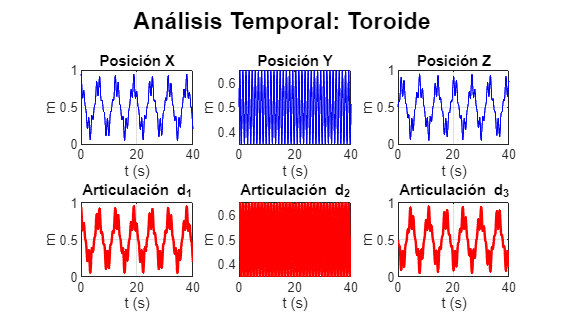


% Análisis Temporal
plotAnalisisTemporal(t_tor, x_tor, y_tor, z_tor, x0_tor, y0_tor, z0_tor, d1_tor, d2_tor, d3_tor, 'Toroide');

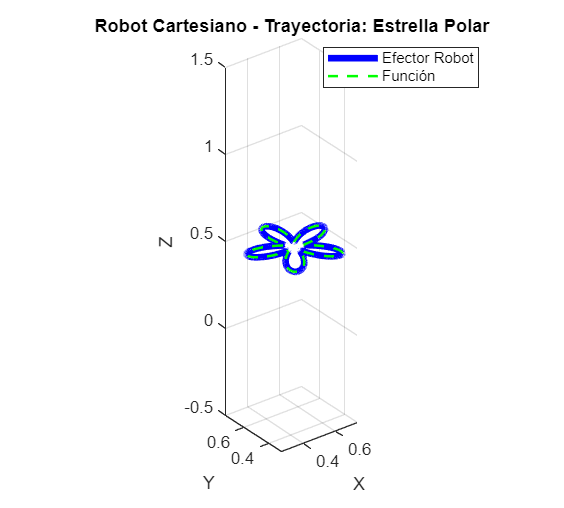


%% ==========================================================
%  TRAYECTORIA 4: ESTRELLA POLAR
%  ==========================================================
t_pol = 0:0.01:2*pi; % Un ciclo completo y suave
xc = 0.5; yc = 0.5;
r_pol = 0.15 + 0.1 .* sin(5 * t_pol); % 5 picos

x_pol = xc + r_pol .* cos(t_pol);
y_pol = yc + r_pol .* sin(t_pol);
z_pol = 0.5 .* ones(1, length(t_pol)); % Estrella plana a media altura

N_pol = length(t_pol);
x0_pol = zeros(1, N_pol); y0_pol = zeros(1, N_pol); z0_pol = zeros(1, N_pol);
d1_pol = zeros(1, N_pol); d2_pol = zeros(1, N_pol); d3_pol = zeros(1, N_pol);

for i = 1:N_pol
    [d1_pol(i), d2_pol(i), d3_pol(i)] = cinv_Cartesiano(l1, x_pol(i), y_pol(i), z_pol(i));
    [x0_pol(i), y0_pol(i), z0_pol(i)] = cdir_Cartesiano(d1_pol(i), d2_pol(i), d3_pol(i), l1);
end

% Gráfica 3D
figure('Name', 'Trayectoria 4: Estrella Polar (3D)', 'Position', [50, 50, 500, 450]);
plot3(x0_pol, y0_pol, z0_pol, 'b', 'LineWidth', 4); hold on;
plot3(x_pol, y_pol, z_pol, '--g', 'LineWidth', 1.5);
axis equal; grid on; title('Robot Cartesiano - Trayectoria: Estrella Polar');
legend("Efector Robot", "Función", 'Location', 'best'); xlabel('X'); ylabel('Y'); zlabel('Z'); view(3);

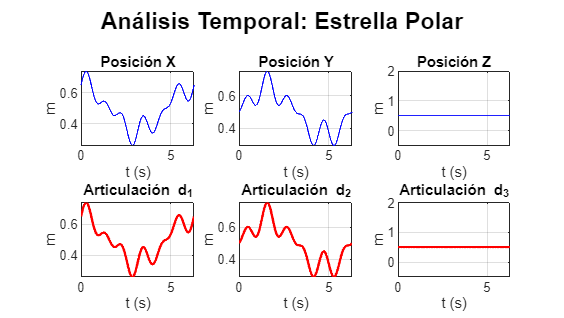


% Análisis Temporal
plotAnalisisTemporal(t_pol, x_pol, y_pol, z_pol, x0_pol, y0_pol, z0_pol, d1_pol, d2_pol, d3_pol, 'Estrella Polar');


%% ==========================================================
%  FUNCIONES LOCALES
%  ==========================================================

% --- Cinemática Inversa (Robot Cartesiano PPP) ---
function [d1, d2, d3] = cinv_Cartesiano(l1, Px, Py, Pz)
    d1 = Px;
    d2 = Py;
    d3 = l1 - Pz; 
end

% --- Cinemática Directa (Robot Cartesiano PPP) ---
function [Px, Py, Pz] = cdir_Cartesiano(d1, d2, d3, l1)
    H1_0 = round(Hrz(90)) * Htz(l1) * Htx(0) * round(Hrx(90));
    H2_1 = round(Hrz(90)) * Htz(d1) * Htx(0) * round(Hrx(90));
    H3_2 = round(Hrz(90)) * Htz(d2) * Htx(0) * round(Hrx(-90));
    H4_3 = round(Hrz(0)) * Htz(d3) * Htx(0) * round(Hrx(0));
    
    H4_0 = H1_0 * H2_1 * H3_2 * H4_3;
    
    Px = H4_0(1,4); 
    Py = H4_0(2,4); 
    Pz = H4_0(3,4);
end

function plotAnalisisTemporal(t, x, y, z, x0, y0, z0, d1, d2, d3, titulo)
    % Crea una figura con 6 subgráficas comparando coordenadas y perfiles articulares
    figure('Name', ['Análisis Temporal: ', titulo], 'Position', [600, 500, 800, 450]);
    sgtitle(['Análisis Temporal: ', titulo], 'FontWeight', 'bold', 'FontSize', 14);
    
    subplot(2,3,1); plot(t, x, '--g', t, x0, 'b'); 
    title('Posición X'); xlabel('t (s)'); ylabel('m'); grid on;
    
    subplot(2,3,2); plot(t, y, '--g', t, y0, 'b'); 
    title('Posición Y'); xlabel('t (s)'); ylabel('m'); grid on;
    
    subplot(2,3,3); plot(t, z, '--g', t, z0, 'b'); 
    title('Posición Z'); xlabel('t (s)'); ylabel('m'); grid on;
    
    % Para el Cartesiano, las articulaciones son prismáticas (metros)
    subplot(2,3,4); plot(t, d1, 'r', 'LineWidth', 1.5); 
    title('Articulación d_1'); xlabel('t (s)'); ylabel('m'); grid on;
    
    subplot(2,3,5); plot(t, d2, 'r', 'LineWidth', 1.5); 
    title('Articulación d_2'); xlabel('t (s)'); ylabel('m'); grid on;
    
    subplot(2,3,6); plot(t, d3, 'r', 'LineWidth', 1.5); 
    title('Articulación d_3'); xlabel('t (s)'); ylabel('m'); grid on;
end